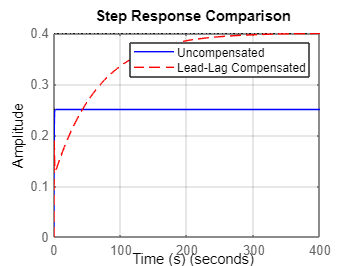

%=========================================================
% Lead-Lag Compensation for First-Order System
% System: G(s) = 1/(s + 3)
% Author: Joshua Wambua
% Date: 9-Nov-2025
%=========================================================

clc; clear; close all;

%---------------------------
% 1. Define the plant
%---------------------------
s = tf('s');             % Define Laplace variable
G = 1/(s + 3);           % First-order system

%---------------------------
% 2. Lead compensator design
%---------------------------
K_lead = 2;              % gain
z_lead = 1;              % lead zero
p_lead = 5;              % lead pole
G_lead = K_lead * (s + z_lead)/(s + p_lead);

%---------------------------
% 3. Lag compensator design
%---------------------------
z_lag = 0.05;            % lag zero
p_lag = 0.01;            % lag pole
G_lag = (s + z_lag)/(s + p_lag);

%---------------------------
% 4. Combined compensator
%---------------------------
G_comp = G_lead * G_lag; % total compensator
L_comp = G_comp * G;     % open-loop compensated
T_comp = feedback(L_comp, 1); % closed-loop compensated

% Uncompensated closed-loop
T0 = feedback(G, 1);

%---------------------------
% 5. Step response comparison
%---------------------------
figure;
step(T0, 'b', T_comp, 'r--');
grid on;
legend('Uncompensated','Lead-Lag Compensated');
title('Step Response Comparison');
xlabel('Time (s)');

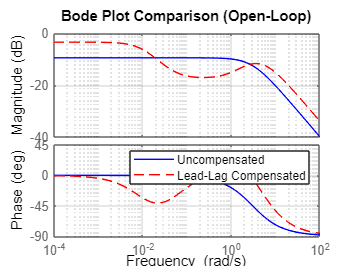

ylabel('Amplitude');

%---------------------------
% 6. Bode plot comparison
%---------------------------
figure;
bode(G, 'b', L_comp, 'r--'); % Plot uncompensated and compensated
grid on;
legend('Uncompensated','Lead-Lag Compensated');
title('Bode Plot Comparison (Open-Loop)');

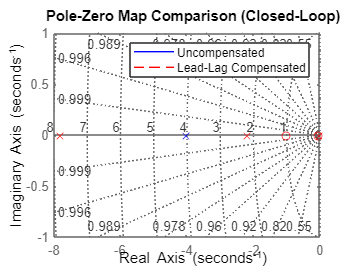


%---------------------------
% 7. Pole-Zero Map
%---------------------------
figure;
pzmap(T0, 'b', T_comp, 'r--');
grid on;
legend('Uncompensated','Lead-Lag Compensated');
title('Pole-Zero Map Comparison (Closed-Loop)');


%---------------------------
% 8. Step Response Info
%---------------------------
disp('=== Step Response Info ===');

=== Step Response Info ===


disp('Uncompensated System:');

Uncompensated System:


disp(stepinfo(T0));

         RiseTime: 0.5493
    TransientTime: 0.9780
     SettlingTime: 0.9780
      SettlingMin: 0.2261
      SettlingMax: 0.2500
        Overshoot: 0
       Undershoot: 0
             Peak: 0.2500
         PeakTime: 2.6365



disp('Lead-Lag Compensated System:');

Lead-Lag Compensated System:


disp(stepinfo(T_comp));

         RiseTime: 132.7656
    TransientTime: 242.4439
     SettlingTime: 242.4439
      SettlingMin: 0.3600
      SettlingMax: 0.3995
        Overshoot: 0
       Undershoot: 0
             Peak: 0.3995
         PeakTime: 428.7159




% Steady-state error
dc0 = dcgain(T0);
dc1 = dcgain(T_comp);
fprintf('\nUncompensated DC Gain = %.4f (Ess = %.4f)\n', dc0, 1-dc0);


Uncompensated DC Gain = 0.2500 (Ess = 0.7500)


fprintf('Compensated DC Gain = %.4f (Ess = %.4f)\n', dc1, 1-dc1);

Compensated DC Gain = 0.4000 (Ess = 0.6000)
